# CÓDIGO DESENVOLVIDO BASEADO NO MÉTODO DOS ELEMENTOS FINITOS UTILIZANDO A FORMULAÇÃO GUF 

# CLEANING

clc; clear; close all

## APPROXIMATION

APP = [2 2 2]; 

## MESH

mesh.ney = 42; % number of elements in Y
mesh.nex = 14; % number of elements in X
mesh.Lx = 1;   % length in X 
mesh.Ly = 3;   % length in Y
fprintf('a = %d',mesh.Lx)

a = 1

fprintf('b = %d',mesh.Ly)

b = 3

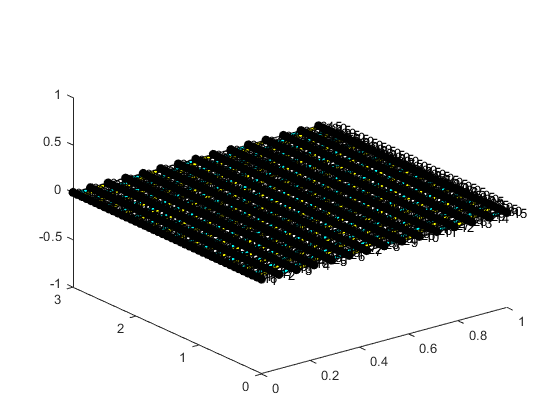

mesh.type = 'Q4';
[ mesh ] = create_mesh( mesh );

## THEORY

theory = 'EQ'; % EQ - Equivalent Single Layer
               % LW - Layerwise
               if strcmp(theory,'EQ')
                   fprintf('Equivalent Single Layer')
               elseif strcmp(theory,'LW')
                   fprintf('Layerwise')
               end

Equivalent Single Layer

## MATERIAL - ISOTROPIC

mat(1).E = 1; % YOUNG MODULUS
mat(1).nu = 0.25;  % POISSON RATIO

## GEOMETRY

geo(1).h = 1;         % THICKNESS
geo(1).z_top = geo(1).h/2;
geo(1).z_low =-geo(1).h/2;
geo(1).theta = 0;     % ANGLE
NL = length(geo);     % NUMBER OF LAYERS

## DEGREES OF FREEDOM

[ dof ] = degrees_of_freedom( APP, mesh, NL, theory );


Layer has 3 degrees of freedom in X direction 
Layer has 3 degrees of freedom in Y direction 
Layer has 3 degrees of freedom in Z direction 

Laminate has 3 degrees of freedom in X direction 
Laminate has 3 degrees of freedom in Y direction 
Laminate has 3 degrees of freedom in Z direction 


## BOUNDARY CONDITIONS

typeofBC = 'ssss'; % 'ssss' = Simply supported
                   % 'cccc' = Clamped
if strcmp(typeofBC,'ssss')
    fprintf('Simply supported plate')
elseif strcmp(typeofBC,'cccc')
    fprintf('Clamped plate')
end

Simply supported plate

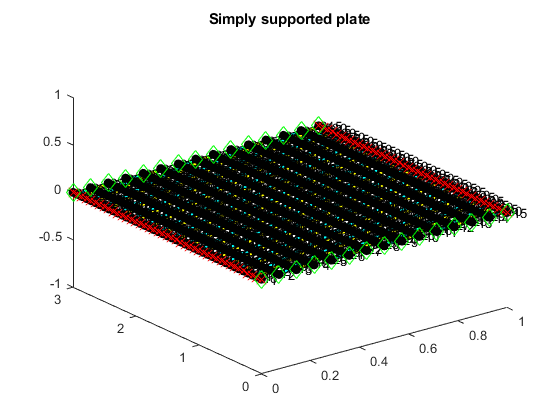


[ fixedNode ] = Boundary_Condition( mesh, typeofBC );

[ dof ] = free_DOF( dof, fixedNode, mesh  );

## APPLIED PRESSURE

type_Load = 'sinusoidal'; % UNIFORM LOAD = uniform
                       % SINUSOIDAL LOAD = sinusoidal
%    X Y Z
P = [0 0 100;  % TOP
     0 0 0]; % BOTTOM

## COMPUTING GLOBAL STIFFNESS

for ply = 1 : NL
    % COMPUTING PLY STIFFNESS
    [ stiffness ] = classic_Hook_iso( mat, geo, ply );
    
    %COMPUTING KERNELS
    [ Z ] = z_matrix( APP, geo, ply, stiffness, theory );
    [ S ] = shape_function( mesh );
    KE = local_stiffness( dof, mesh, S, Z );
end
[ KG ] = global_stiffness_matrix( dof, KE, mesh );

## COMPUTING LOAD VECTOR

% [ D ] = D_ESL( dof, NL, geo );
[ D ] = D_matrices( geo, dof, theory, NL );
switch type_Load
    case 'sinusoidal'
        [ Fg ] = sinusoidal_load( dof, mesh, D, P );
    case 'uniform' 
        [ Fg ] = uniform_load( dof, mesh, D, P );
end

## COMPUTING DISPLACEMENT

U = zeros(size(KG,1),1);
U(logical(dof.free),1) = sparse(KG(logical(dof.free), logical(dof.free)))\sparse(Fg(logical(dof.free), 1));

## POST-PROCESSING

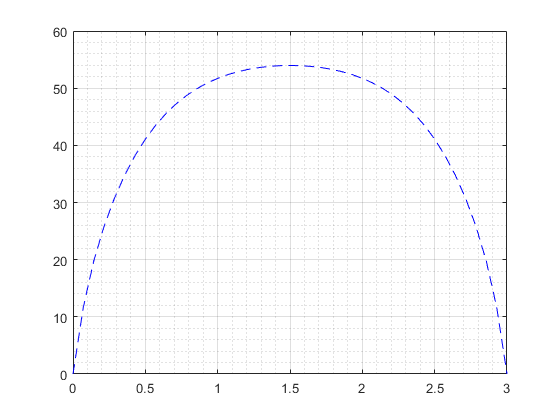

post_processing( dof, geo, mesh, U )